# **7C - TEMA D'ESAME - 2DOF CONTROLLER**

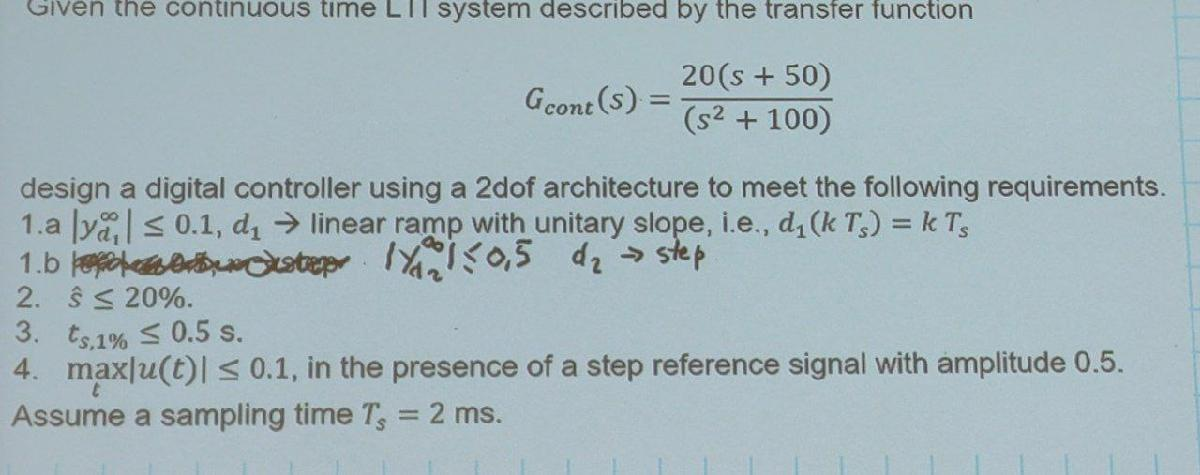

ts = 0.002;
z = tf('z',ts);
s = tf('s');
Gcont = (20*(s+50)/(s^2+100));

i due poli a` +-j10 `sono per forza mappati sul bordo del cerchio unitario quando passo nel dominio discreto (non sembra da matlab)

G = zpk(c2d(Gcont,ts,'zoh'))

G =
 
  0.041997 (z-0.9048)
  -------------------
    (z^2 - 2z + 1)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.



da questa funzione di trasferimento sembra che i poli siano in 1 ma non è vero

[zG, pG, kG] = zpkdata(G,'v')           %i poli non sono in 1 ma sono due poli complessi (approssimazione di zpk)

zG = 0.9048

pG =    0.9998 + 0.0200i
   0.9998 - 0.0200i


kG = 0.0420

zpk fa delle approssimazioni per questo i poli che mi escono sono diversi da quelli che mi aspetterei solo vedendo la funzione di trasferimento

Computando la MAGNITUDE trovo che è 1

val = abs(pG)                          % il modulo è 1 di entrambi

val =      1
     1


Quindi devo computare più precisamente

A = conv([1 -pG(1)], [1 -pG(2)]);
B = kG*[1 -zG];

Secondo questi coefficienti la $G\left(z\right)=\frac{0\ldotp 041997\left(z-0\ldotp 9048\right)}{z^2 +1\ldotp 9996z+1}$

### **STEADY STATE REQUIREMENTS ANALYSIS**

1a)        $|y_{d_1 }^{\infty } |\le 0\ldotp 1\;\textrm{con}\;d_1 \;\textrm{rampa}\;\left(d_1 \left({\textrm{kT}}_s \right)={\textrm{kT}}_s \right)\to l_2 =1\to \textrm{errore}=\frac{\delta_1 }{K_{l_2 } }T\;$

              
$$C\left(z\;\right)=\frac{S\left(z\right)}{\left(z-1\right)R^{\prime } \left(z\right)}$$


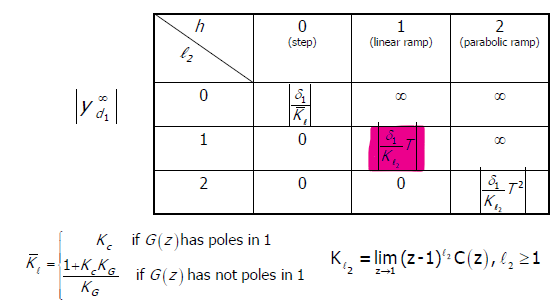

              Serve una *condizione aggiuntiva* per garantire l'errore limitato $\to \frac{\delta_1 }{K_{l_2 } }T\;\le 0\ldotp 1\;\textrm{con}\;K_{l_2 } =\lim_{z\to 1} \left(z-1\right)C\left(z\right)$ (analizziamo dopo la costruzione del controllore)

1b)         $|y_{d_2 }^{\infty } |\le 0\ldotp 5,\textrm{con}\;d_2 =\epsilon \left(\textrm{kTs}\right)\to l=0\;\textrm{ma}\;\textrm{per}\;1a\;\textrm{dobbiamo}\;\textrm{avere}\;l=1\;\left(e\;\textrm{cioè}\;\;|{\mathit{\mathbf{y}}}_{{\mathit{\mathbf{d}}}_2 }^{\infty } |=0\right)\to \textrm{questa}\;\textrm{condizione}\;è\;\textrm{automaticamente}\;\textrm{verificata}\ldotp$

              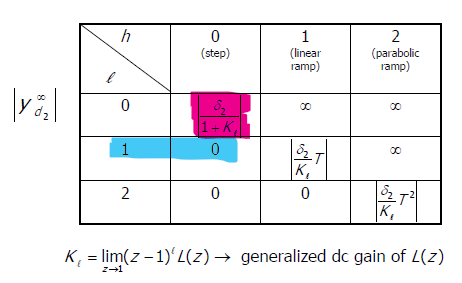

                Bisogna rispettarle entrambe e verificare la più restrittiva (in questo caso 1a)

*meglio non aggiungere poli in uno che non servono

### TRANSIENT REQUIREMENT ANALYSIS

2a)         $\hat{s} \le 20%$ 

s_hat = 0.2;

                
$$\zeta =\frac{|\;\textrm{logŠ}\;|}{\sqrt{\pi^2 +{\left(\textrm{logŠ}\right)}^2 }}\;$$


zeta = abs(log(s_hat))/(sqrt(pi^2 + (log(s_hat))^2));

2b)        $t_{s,1%} \le 0\ldotp 5s$

ts1 = 0.5;

              
$$\omega_n =$$
 
$$\frac{{-\log \left(0\ldotp 01\right)} }{t_{s,1%} \cdot \zeta }$$


wn = -log(0.01)/(zeta*ts1);

### **VISUALIZZO LA PZMAP**

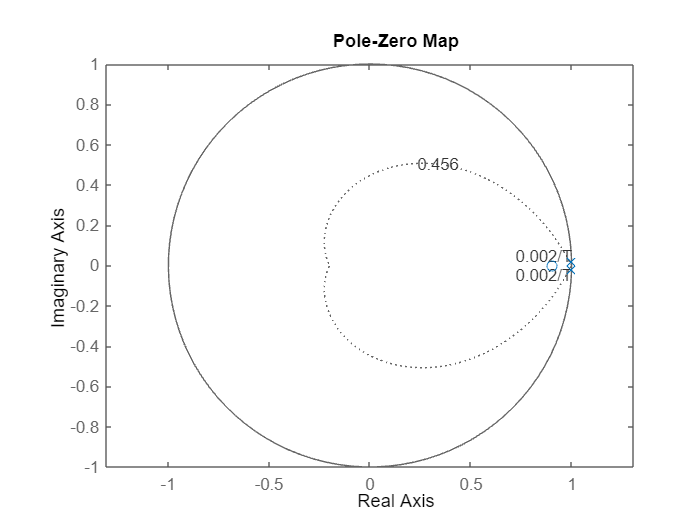

figure
pzmap(G)
axis('equal')
zgrid(zeta,ts)

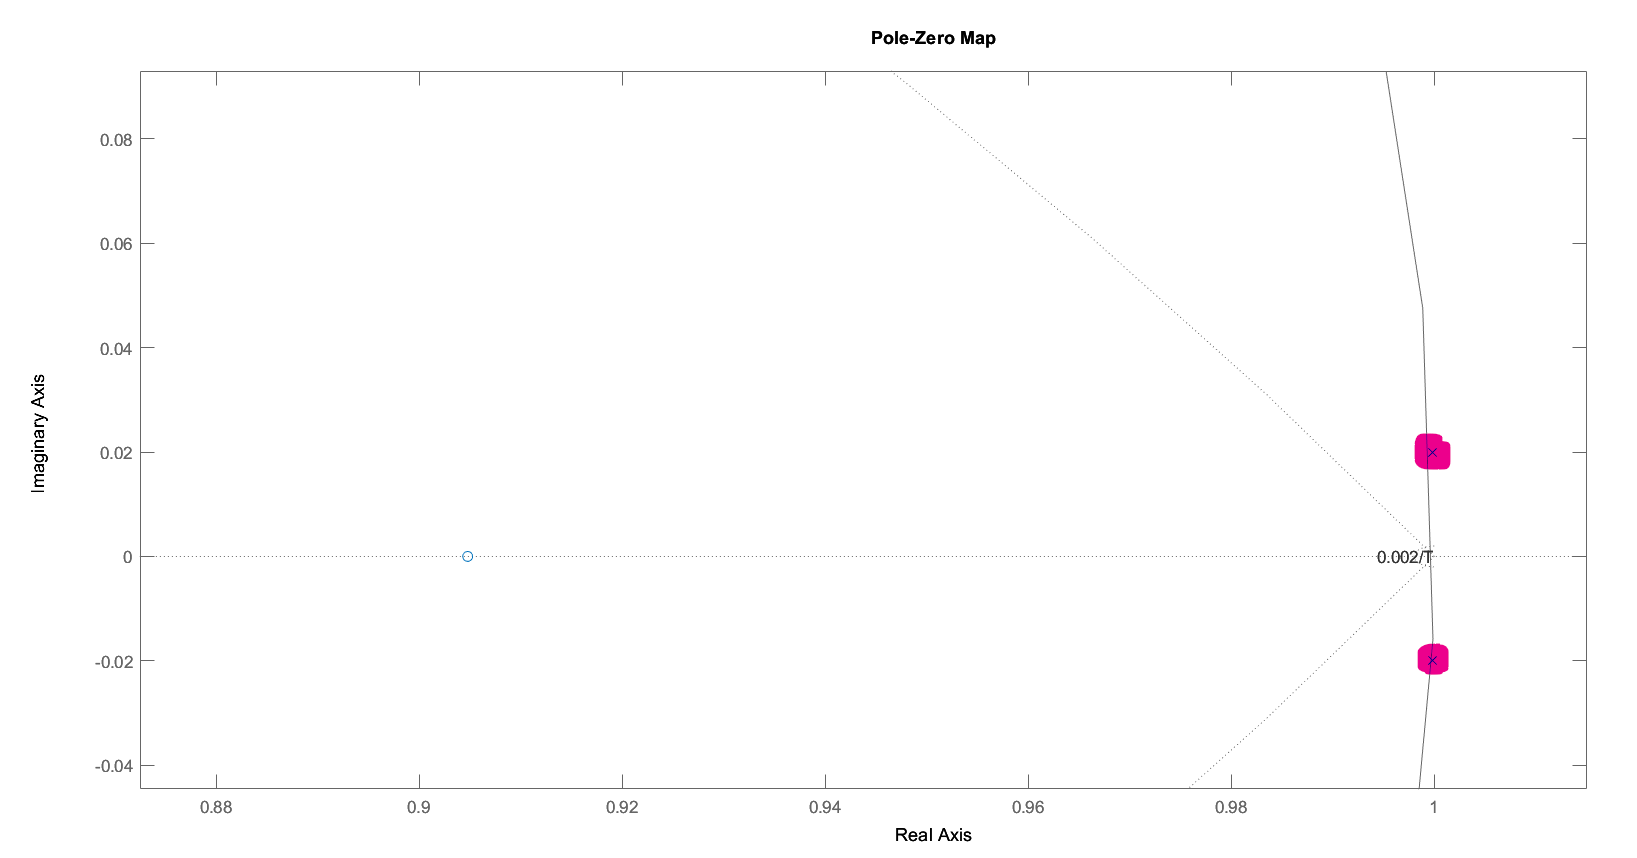

i poli stanno sul border dell'unitary circle, ma la stability è data dalla magnitude < 1

The immaginary axis is inside the unitary circle

### DESIGN SETTINGS - Cancello tutti gli zeri e i poli in base al requisito di $\zeta$

Dentro il dominio di $\zeta >0\ldotp 4559$ cancello tutti i poli e gli zeri - quelli da cancellare vanno i B+ e A+

In questo caso devo solo cancellare lo zero in `zG`

A_plus = 1;
A_minus = A;
B_plus = [1 -zG];       % B+ e A+ devono essere monici -> zeta deve essere moltiplicata per 1
B_minus = kG;           % il gain deve stare sempre nel B- (mai nel B+)

### DEGREE CONDITIONS


$$\begin{array}{l}
\deg \left(S^{\prime } \left(z\right)\right)=l+\deg \left(A^- \left(z\right)\right)-1=l_1 +l_2 +\deg \left(A^- \left(z\right)\right)-1+1=\;3\\
\deg \left(R^{\prime } \left(z\right)\right)=\deg \left(A^{\prime } \left(z\right)\right)-\deg \left(B^+ \left(z\right)\right)+l_1 -1+1=1\\
\deg \left(A_m \left(z\right)\right)=l+\deg \left(A^{\prime } \left(z\right)\right)+\deg \left(A^- \left(z\right)\right)+l_1 -\deg \left(B^+ \left(z\right)\right)-1+1=3\;\left(4\;\textrm{poli}\;\textrm{da}\;\textrm{piazzare}\;\textrm{in}\;C\left(z\right)\right)
\end{array}$$
 

Rispetto alle formule solite qui ho un *+1 *alla fine, dovuto alle *condizioni aggiuntive*

### ASSIGNING THE POLES

I primi due poli sono sempre computati allo stesso modo come complessi coniugati, invece il 3° polo deve essere reale (perchè i poli complessi creano problemi con la transfer function) e con una costante di tempo più veloce delle altre (per non avere problemi con la futura $F\left(z\right)$, che mi permette di cancellare solo una parte degli zeri)

In generale quindi scelgo sempre gli additional poles come reali

In questo caso scelgo` p3=p4 `e posso sceglierli coincidenti perchè ne ho solo 2 aggiuntivi 

Se ne avessi più di 2 sarebbe meglio sceglierli leggermente differenti (x es. $5\ldotp 02\;\zeta {\;\omega }_n$ o $5\ldotp 01\;\zeta \;\omega_n$)

p1_c = -zeta*wn + j*wn*sqrt(1-zeta^2); 
p2_c = -zeta*wn - j*wn*sqrt(1-zeta^2);
p3_c = -5*zeta*wn;
p4_c = p3_c;
p1 = exp(ts*p1_c);
p2 = exp(ts*p2_c);
p3 = exp(ts*p3_c);
p4 = p3;

Il controllore sarà della forma $C\left(z\right)=\frac{s_3 z^3 +s_2 z^2 +s_1 z+s_0 }{\left(z-1\right)B^+ \left(z\right)\left(r_1 z+r_0 \right)}\;$

        
$$A_m \left(z\right)=\gamma_4 z^4 +\gamma_3 z^3 +\gamma_2 z^2 +\gamma_1 z+\gamma_0$$


Am = poly([p1 p2 p3 p4])

Am =     1.0000   -3.7862    5.3747   -3.3902    0.8017


### DIOPHANTINE EQUATION


$$\left(z-1\right){\;A}^+ \left(z\right){\;R}^{\prime } \left(z\right)+B^- \left(z\right)\;S\left(z\right)=A_m \left(z\right)$$


Adioph = conv([1 -1], A_minus)          % 4 coefficienti

Adioph =     1.0000   -2.9996    2.9996   -1.0000


Bdioph = B_minus                        % 1 coefficiente

Bdioph = 0.0420

Ultima riga della Silvester Matrix (data dalla *condizione aggiuntiva*)

Soddisfare la condizione aggiuntiva: $|y_{d_1 }^{\infty } |\le 0\ldotp 1\to \lim_{z\to 1} \left(z-1\right)C\left(z\right)=\frac{s_3 +s_2 +s_1 +s_0 }{B^+ \left(1\right)\left(r_1 +r_0 \right)}\;\to T_s \cdot B\left(1\right)\left(r_1 +r_0 \right)-0\ldotp 1\left(s_3 +s_2 +s_1 +s_0 \right)=0$

quindi sotto $A_{\textrm{dioph}}$ metteremo ciò che moltiplica la $\left(r_1 +r_0 \right)$ 

           sotto $B_{\textrm{dioph}}$ metteremo ciò che moltiplica la $\left(s_3 +s_2 +s_1 +s_0 \right)$

aggA1 = polyval(B_plus, 1);
aggA = aggA1*ts;
aggB = -0.1;

Definisco la matrice $M_s$ : 

M_s = [[Adioph(:); 0; aggA],[0; Adioph(:); aggA],[0; Bdioph(:); 0; 0; 0; aggB],...
    [0; 0; Bdioph(:); 0; 0; aggB],[0; 0; 0; Bdioph(:); 0; aggB], [0; 0; 0; 0; Bdioph(:); aggB]]

M_s =     1.0000         0         0         0         0         0
   -2.9996    1.0000    0.0420         0         0         0
    2.9996   -2.9996         0    0.0420         0         0
   -1.0000    2.9996         0         0    0.0420         0
         0   -1.0000         0         0         0    0.0420
    0.0002    0.0002   -0.1000   -0.1000   -0.1000   -0.1000


### COMPUTATION OF C(z)

Mi trovo quindi grazie alla matrice 6x1       $\Gamma =\left\lbrack \begin{array}{c}
\gamma_4 \\
\gamma_3 \\
\gamma_2 \\
\gamma_1 \\
\gamma_0 \\
0
\end{array}\right\rbrack$         anche la matrice 6x1         $\theta =\left\lbrack \begin{array}{c}
r_1 \\
r_0 \\
s_3 \\
s_2 \\
s_1 \\
s_0 
\end{array}\right\rbrack$     con le soluzioni della $C\left(z\right)$

e trovo la matrice $\Gamma$ come

Gamma = [Am 0]'

Gamma =     1.0000
   -3.7862
    5.3747
   -3.3902
    0.8017
         0


e la matrice $\theta$ come

theta = M_s\Gamma;

A questo punto sapendo che i primi 2 valori corrispondono alla $R^{\prime } \left(z\right)$ e gli ultimi 4 alla $S^{\prime } \left(z\right)$ mi distinguo i due vettori e li orizzontalizzo

R1 = theta(1:2)';
S1 = theta(3:6)';

Grazie alla formula generale del controllore :

                
$$C\left(z\right)=\frac{A^+ \left(z\right)\;S^{\prime } \left(z\right)}{\left(z-1\right)B^+ \left(z\right)R^{\prime } \left(z\right)}=\frac{S\left(z\right)}{R\left(z\right)}$$


mi posso trovare $S\left(z\right)$ e $R\left(z\right)$ e anche finalmente $C\left(z\right)$

R = conv([1 -1] ,conv(B_plus, R1));
S = conv(A_plus, S1);
C = minreal(zpk(tf(S,R,ts)),1e-2)

C =
 
  1.3878 (z-0.7674) (z^2 - 1.966z + 0.9671)
  -----------------------------------------
         (z-1) (z-0.9048) (z-0.8449)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.



### 2DOF DESIGN


$$F\left(z\right)=\frac{T^{\prime } \left(z\right)}{S^{\prime } \left(z\right)}\;\deg \left(S^{\prime } \right)=3\to \deg \left(T^{\prime } \right)=3,T^{\prime } =k_T \tilde{T} \to \tilde{T} =$$


1                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        